# Discritisation

Disctitising the state equations for both temperature, SoC, and RC. S.t

xdot = f(x,i)

v_out = f(x(2)) + iR0 + x(3)

delta_temp =  clear

file_loc = "..\..\..\cycle_exports\MOLI_28\";
cycle_number = "46";
filepath = strcat(file_loc, sprintf("MOLI_cycle_%s.mat", cycle_number));
load(filepath);
try
    solution_unbound
catch exception
    disp("Mhmmmmm")
end

time = 0:5:14000;
i_input = interp1(tt,u1',time,"previous");
i_size = length(i_input);
v1 = ones(1,i_size)*0.1;
z = ones(1,i_size);
DT = zeros(1,i_size);
states = [v1; z; DT];
params = length(solution_unbound.p)

params = 15

for i = 1:i_size-1
i_curr = i_input(i);
Ts = time(i+1) - time(i);
[A, B] = discrit(solution_unbound.p,Ts);
states(:,i+1) = A*states(:,i) + B*[i_curr;i_curr.^2;states(1,i).*i_curr];
end
Sim_DT = states(3,:)

Sim_DT =          0    0.0075    0.0156    0.0244    0.0338    0.0436    0.0539    0.0646    0.0756    0.0870    0.0987    0.1106    0.1227    0.1351    0.1476    0.1603    0.1731    0.1860    0.1990    0.2121    0.2252    0.2384    0.2517    0.2649    0.2782    0.2915    0.3049    0.3182    0.3315    0.3448    0.3580    0.3713    0.3845    0.3977    0.4108    0.4239    0.4370    0.4500    0.4629    0.4759    0.4887    0.5015    0.5143    0.5270    0.5396    0.5522    0.5647    0.5771    0.5895    0.6018


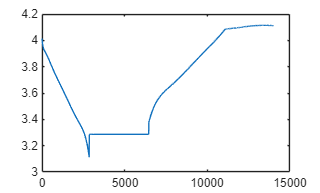

fix.poly.xe = zeros(params - 6,1);
Sim_V = polymodel(fix,solution_unbound.p,states(2,:),1)  + states(1,:) + i_input.*(solution_unbound.p(params-3));
plot(time,Sim_V)

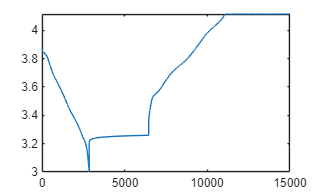

plot(tt,y)

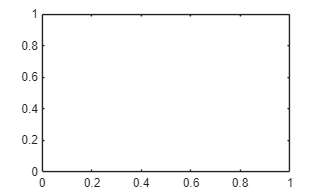

plot(tt,tp)

%[trr,trw] = discrit_solver(t_input,i_input,solution_unbound.p,1)